# Aufgabe 2: Erkennung von Sprachkommandos

Hier soll ein vollverbundenes Neuronales Netz zur Erkennung von Sprachkommandos erstellt werden. Um einen brauchbaren Klassifikator zu erhalten, ist es ungünstig, mit den Audio-Rohdaten zu arbeiten. Ein besserer Ansatz besteht darin, zuerst aus jeder Audio-Datei ein Spektrogramm zu erstellen und damit ein Neuronales Netz zu trainieren.

### Aufgabe 2 (a) Hintergrund wiederholen

Wiederholen Sie die Begriffe *Kurzzeit-FFT* und *Spektrogramm* aus Ihrer Lieblingsvorlesung zur digitalen Signalverarbeitung.

### Aufgabe 2 (b) Einlesen der Daten

Das Einlesen der Audio-Dateien kann mit einem `audioDatastore`-Objekt (Doku lesen!) erledigt werden, was den ganzen Prozess deutlich vereinfacht.

adsTrain = audioDatastore(fullfile('Daten', 'Sprachkommandos', 'train'), ...
   "IncludeSubfolders",true, 'LabelSource','foldernames');
adsTest = audioDatastore(fullfile('Daten', 'Sprachkommandos', 'test'), ...
   "IncludeSubfolders",true, 'LabelSource','foldernames');
% Klassenverteilung der Trainingsdaten auflisten:
tabulate(adsTrain.Labels);

  Value    Count   Percent
     go      750     25.00%
   left      750     25.00%
  right      750     25.00%
   stop      750     25.00%


Ein Beispiel für ein Spektrogramm ansehen:

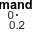

[~, fs] = audioread(adsTrain.Files{1});
win = hamming(128); 
[y, i] = adsTrain.read(); 
[specMat, f,t] = spectrogram(y, win, 0, length(win), fs); 
figure; 
pcolor(t, f, abs(specMat));
title(sprintf('Kommando: %s', i.Label)); 
xlabel('Zeit (Sek.)'), ylabel('Frequenz (Hz)');

Parameter festlegen: 

C = length(categories(adsTrain.Labels));    % Anzahl Klassen
nTrain = length(adsTrain.Labels);
nTest = length(adsTest.Labels);
P = numel(specMat);      % Anzahl Merkmale

Trainingsdaten einlesen:

count = 0; 
trainMat = zeros(nTrain,P);
adsTrain.reset();     % Lesepointer auf Anfang setzen
tic
while adsTrain.hasdata()
   % disp(count);
   count = 1 + count;
   [y, i] = adsTrain.read(); 
   assert(i.SampleRate == 8000);   % Haben alle Dateien die gleiche Abtastrate? 
   % Spectrogramm erzeugen und in trainMat schreiben...
   % TODO: ab hier weiter machen!
end
toc

Elapsed time is 10.218203 seconds.


assert(count == nTrain);   % Wurden wirklich alle Daten gelesen? 

Testdaten einlesen:

% TODO: Testdaten einlesen

### Aufgabe 2 (c) Softmax-Modell trainieren

Trainieren Sie zuerst ein Softmax-Modell. Welchen Trainings- und Testfehler erreichen Sie? Stellen Sie auch die Confusion-Matrix graphisch dar (siehe Beispiel-Code zu Kapitel 7).

### Aufgabe 2 (d) Vollverbundes Netz entwerfen

Erstellen Sie ein Neuronales Netz mit mindestens 3 vollverbundenen Schichten. Welchen Trainings- und Testfehler können Sie jetzt erreichen? Stellen Sie ebenfalls die Confusion-Matrix graphisch dar. Versuchen Sie auf einen Testfehler unter 20% zu kommen. 

(P.S.: Versuchen Sie doch mal, die Lernratendämpfung (siehe Ende Kap. 5) beim Training zu aktivieren. Das könnte die Leistung des Netzes verbessern.)